disp('Exercise 1');

Exercise 1



t = [0, 3, 5, 8, 13];
d = [0, 225, 383, 623, 993];
v = [75, 77, 80, 74, 72];

t_query = 10;

p = pchip(t, d); 
v_interp = pchip(t, v); 

d_est = ppval(p, t_query);
v_est = ppval(v_interp, t_query);

fprintf('Estimated position at t = 10: %.2f\n', d_est);

Estimated position at t = 10: 775.06


fprintf('Estimated speed at t = 10: %.2f\n', v_est);

Estimated speed at t = 10: 72.79



disp('Exercise 2');

Exercise 2



x = [1, 2];
fx = [0, 0.6931];
dfx = [1, 0.5];

syms X
H = hermiteInterp(x, fx, dfx);
f_approx = double(subs(H, 1.5));
actual_val = log(1.5);
error = abs(actual_val - f_approx);

fprintf('f(1.5) by Hermite interpolation: %.5f\n', f_approx);

f(1.5) by Hermite interpolation: 0.40905


fprintf('Absolute approximation error: %.5e\n', error);

Absolute approximation error: 3.58489e-03



disp('Exercise 3');

Exercise 3


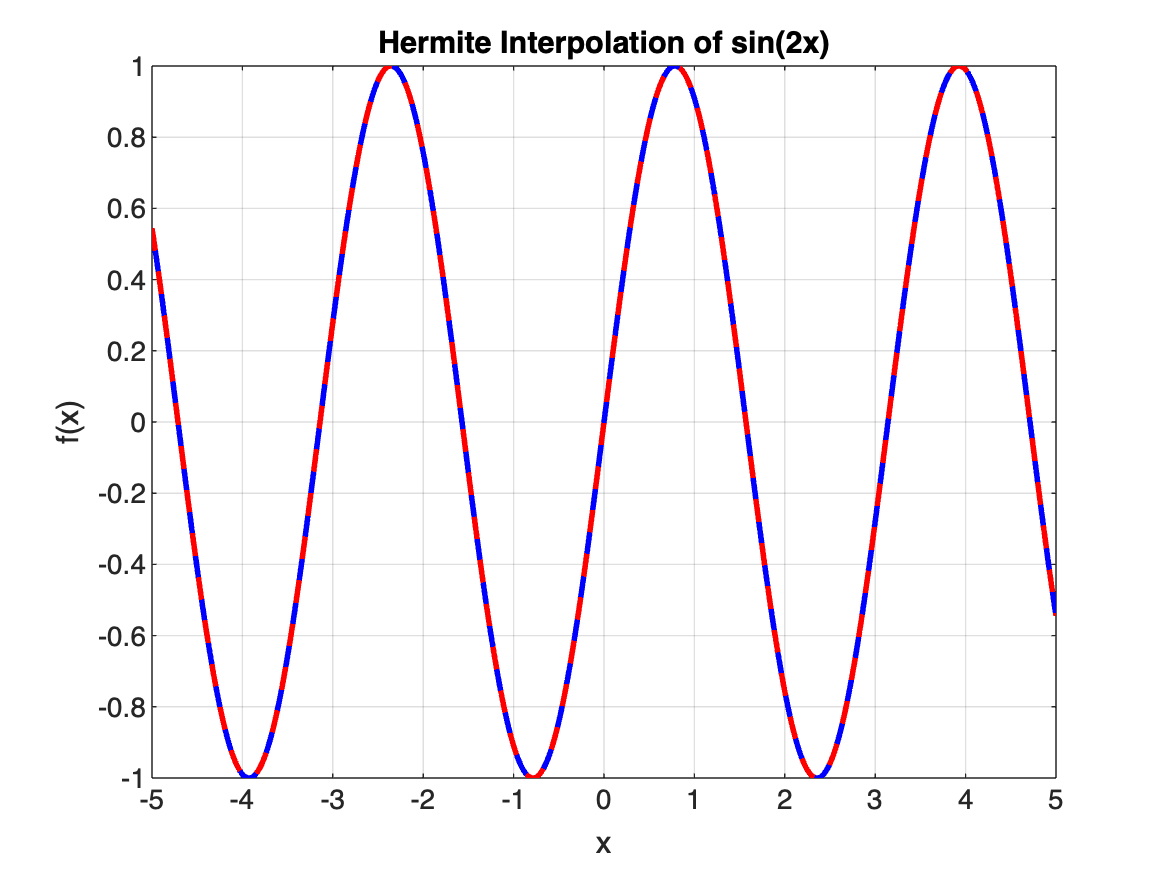


f = @(x) sin(2*x);
X_nodes = linspace(-5,5,15);
Y_nodes = f(X_nodes);
df_nodes = 2*cos(2*X_nodes);

H_interp = hermiteInterp(X_nodes, Y_nodes, df_nodes);

X_vals = linspace(-5,5,1000);
Y_actual = f(X_vals);
Y_interp = double(subs(H_interp, X_vals));

figure;
plot(X_vals, Y_actual, 'b', 'LineWidth', 2); hold on;
plot(X_vals, Y_interp, 'r--', 'LineWidth', 2);
xlabel('x'); ylabel('f(x)');
title('Hermite Interpolation of sin(2x)');
grid on;


function H = hermiteInterp(x, f, df)
    syms X;
    n = length(x);
    Q = zeros(2*n, 2*n);
    Z = zeros(2*n, 1);
    
    for i = 1:n
        Z(2*i-1) = x(i);
        Z(2*i) = x(i);
        Q(2*i-1, 1) = f(i);
        Q(2*i, 1) = f(i);
        Q(2*i, 2) = df(i);
        if i > 1
            Q(2*i-1, 2) = (Q(2*i-1, 1) - Q(2*i-2, 1)) / (Z(2*i-1) - Z(2*i-2));
        end
    end
    
    for j = 3:2*n
        for i = j:2*n
            Q(i, j) = (Q(i, j-1) - Q(i-1, j-1)) / (Z(i) - Z(i-j+1));
        end
    end
    
    H = Q(1,1);
    P = 1;
    for j = 2:2*n
        P = P * (X - Z(j-1));
        H = H + Q(j,j) * P;
    end
end

